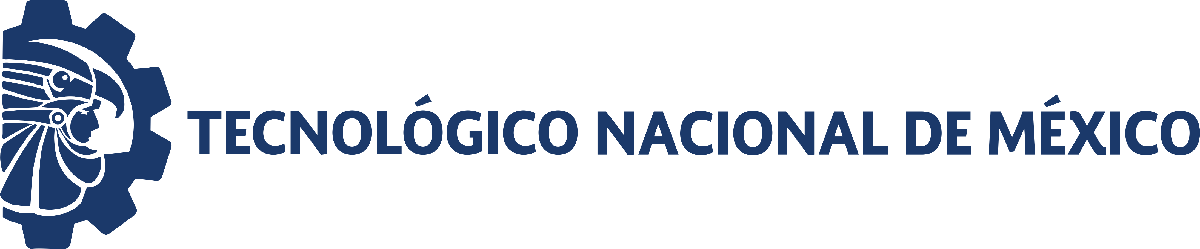                                 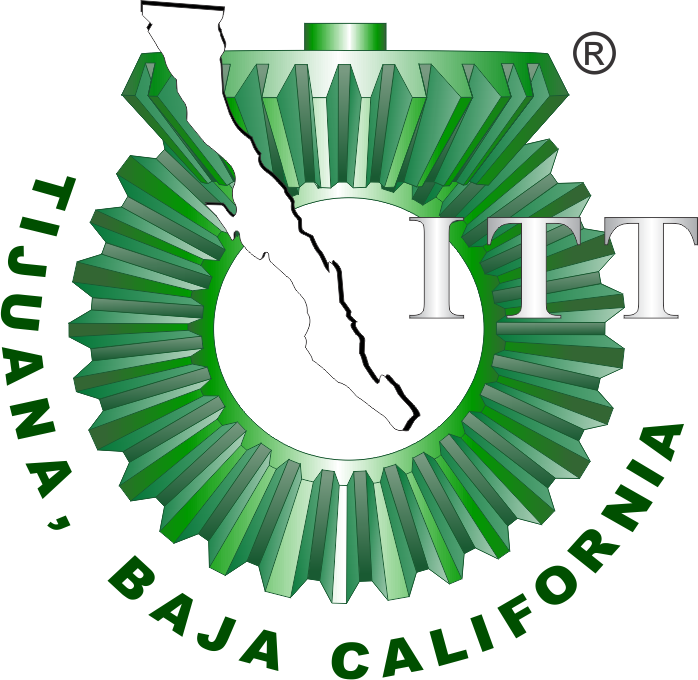

# Práctica tres: Modelado y control del sistema musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

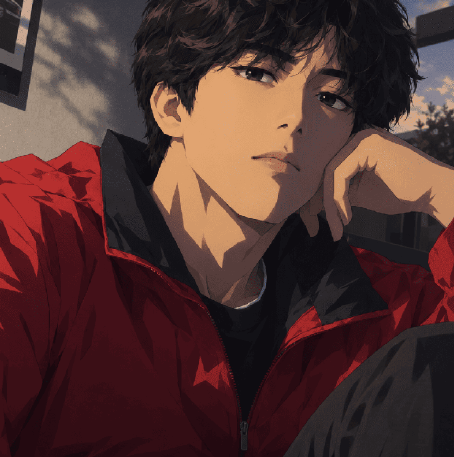

Nombre del alumno: **Martinez Lozano Pedro Damian**

Número de control: 23212806

Correo institucional:** 23212806@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema1.slx')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';


## Respuesta al impulso unitario

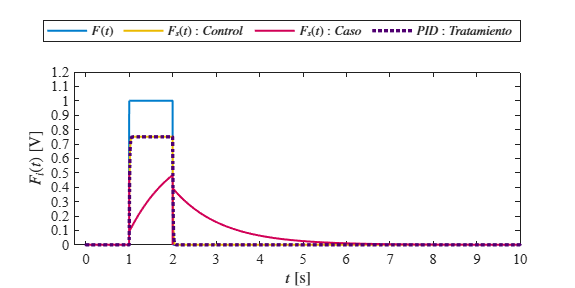

x1 = sim('sistema1.slx',parameters);
plotsignals(x1.t,x1.F,x1.Fsx,x1.Fsy,x1.PID)

## Funcion: Respuesta a las señales

function plotsignals(t,F,Fsx,Fsy,PID)

set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,7,3.5])
set(gca,'fontname','times new roman','fontsize',11)
hold on; grid off; box on;

ctrl1 = [0,125,204]/255;
ctrl2 = [235,185,0]/255;
ctrl3 = [209,0,86]/255;
ctrl4 = [80,0,113]/255;

order = [ctrl1;ctrl2;ctrl3;ctrl4];
colororder(order)

plot(t,F,'-','LineWidth',1.5,'Color',ctrl1)
plot(t,Fsx,'-','LineWidth',1.5,'Color',ctrl2)
plot(t,Fsy,'-','LineWidth',1.5,'Color',ctrl3)
plot(t,PID,':','LineWidth',2.5,'Color',ctrl4)
L = legend('$F(t)$','$F_s(t):Control$', ...
    '$F_s(t):Caso$','$PID: Tratamiento$');
set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
xlabel('$t$ [s]','interpreter','latex')
ylabel('$F_i(t)$ [V]','interpreter','latex')
xlim([-0.25 10]); xticks(0:1:10)
ylim([0 1.2]); yticks(0:0.1:1.2)

exportgraphics(gcf,'_matlab.pdf','ContentType','vector')

end
